PROCESSED DATA ACCORDING TO NGISM.MLX GIVEN IN OUR PROJECT FOLDER

% Load the dataset with correct delimiter (comma, in this case)
filename = 'DACT Easy-Dataset.csv';
opts = detectImportOptions(filename, 'Delimiter', ',');
data = readtable(filename, opts);

% Display column names to verify
disp(data.Properties.VariableNames);

    {'TripID'}    {'TimeStep'}    {'TimeStamp'}    {'Speed'}    {'Acceleration'}    {'Heading'}    {'HeadingChange'}    {'Latitude'}    {'Longitude'}    {'Annotation'}    {'SegmentType'}



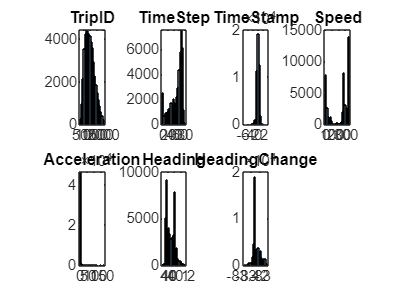


% Histogram for each numerical column
numericData = data{:, varfun(@isnumeric, data, 'Output', 'uniform')};
figure;
for i = 1:size(numericData, 2)
    subplot(2, ceil(size(numericData, 2)/2), i);
    histogram(numericData(:, i), 20);
    title(data.Properties.VariableNames{i});
end

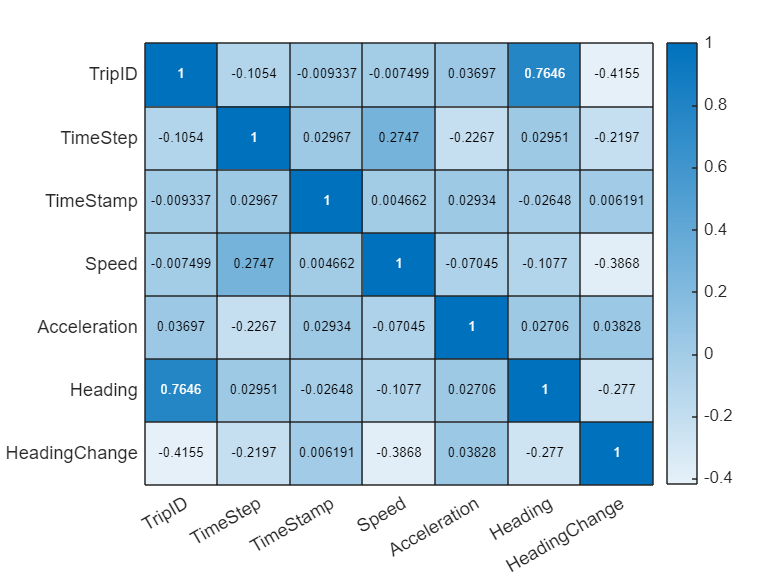

% Correlation heatmap
corrMatrix = corr(numericData);
figure;
heatmap(corrMatrix, 'XDisplayLabels', data.Properties.VariableNames(1:size(corrMatrix, 1)), ...
                'YDisplayLabels', data.Properties.VariableNames(1:size(corrMatrix, 1)));

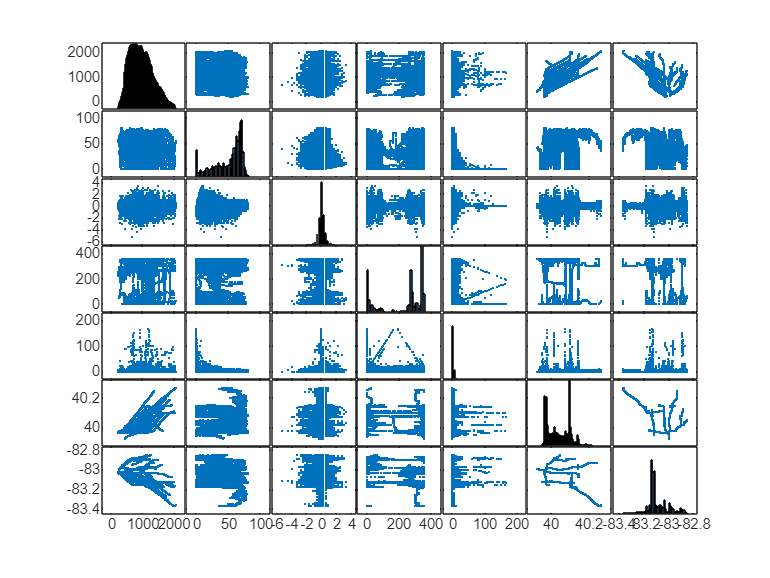


% Scatter plot matrix for numerical features
figure;
plotmatrix(numericData);